clf;
clear;

flower = imread("../images/flower.tif");
[M,N,~] = size(flower)

M = 1200

N = 1600

subplot(1,2,1);
imshow(flower);title('Origin');

flower = im2gray(flower);
level = my_BGT(flower)

level = 0.4326

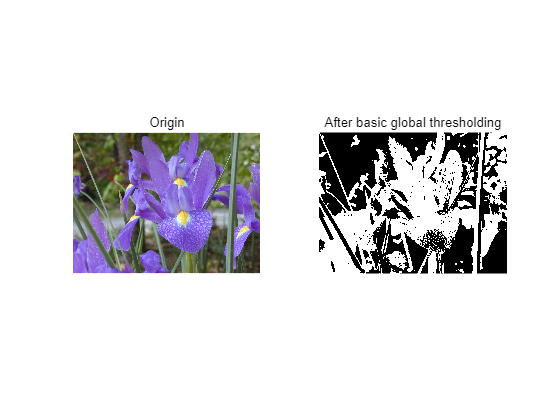

flower_BGT = imbinarize(flower,level);

subplot(1,2,2);
imshow(flower_BGT);title('After basic global thresholding');

function output=my_BGT(image)
    image = im2double(image);
    [M,N] = size(image);
    T0 = 0.001;
    T1 = (max(max(image))+min(min(image)))/2;
    
    cntr1 = 1;
    cntr2 = 1;
    
    G1 = [M,N];
    G2 = [M,N];
    while 1
        for i = 1:M
            for j = 1:N
                if image(i,j)>T1
                    G1(cntr1) = image(i,j);
                    cntr1 = cntr1 + 1;
                else
                    G2(cntr2) = image(i,j);
                    cntr2 = cntr2 + 1;
                end
            end
        end
    
        ave1 = mean(G1);
        ave2 = mean(G2);
        T2 = (ave1+ave2)/2; 

        if abs(T2-T1)<T0
            break;
        end
    
        T1 = T2;
        cntr1 = 1;
        cntr2 = 1;
    end
    
    output = T2;
end